clc; clear; close all;

tic

%% ---------------------------------------------------------
% 1. Load ECG5000 Dataset
%% ---------------------------------------------------------

trainData = load('ECG5000_TRAIN.txt');
testData  = load('ECG5000_TEST.txt');

data = [trainData; testData];

labels = data(:,1);
signals = data(:,2:end);

[numSamples, n] = size(signals);

%% ---------------------------------------------------------
% 2. Convert to Binary (Normal = 0, Abnormal = 1)
%% ---------------------------------------------------------

labels_binary = zeros(size(labels));
labels_binary(labels ~= 1) = 1;

%% ---------------------------------------------------------
% 3. Normalize Signals
%% ---------------------------------------------------------

signals = normalize(signals,2);

%% ---------------------------------------------------------
% 4. Adaptive Toeplitz Convolution Function
%% ---------------------------------------------------------

function y = adaptive_toeplitz(x)

    n = length(x);

    mu = mean(x);
    sigma = std(x);

    alpha = 2;
    beta  = 0.8;

    k = 2 * floor(alpha*sigma + beta*log(n)) + 1;
    k = max(k,5);
    k = min(k,15);

    center = (k+1)/2;
    K = zeros(1,k);

    for i = 1:k
        K(i) = mu + (i-center)*sigma;
    end

    first_col = [x(1), zeros(1,k-1)]';
    first_row = x;

    T = toeplitz(first_col, first_row);

    y = K * T;
    y = y(1:n);

end

%% ---------------------------------------------------------
% 5. Feature Extraction
%% ---------------------------------------------------------

features_toeplitz = zeros(numSamples,7);
features_standard = zeros(numSamples,7);

for i = 1:numSamples

    x = signals(i,:);

    % Toeplitz convolution
    y1 = adaptive_toeplitz(x);

    % Standard convolution
    y2 = conv(x, ones(1,5)/5, 'same');

    % Toeplitz features
    features_toeplitz(i,1) = mean(y1);
    features_toeplitz(i,2) = std(y1);
    features_toeplitz(i,3) = max(y1)-min(y1);
    features_toeplitz(i,4) = sum(abs(diff(y1)));
    features_toeplitz(i,5) = skewness(y1);
    features_toeplitz(i,6) = kurtosis(y1);
    features_toeplitz(i,7) = rms(y1);

    % Standard convolution features
    features_standard(i,1) = mean(y2);
    features_standard(i,2) = std(y2);
    features_standard(i,3) = max(y2)-min(y2);
    features_standard(i,4) = sum(abs(diff(y2)));
    features_standard(i,5) = skewness(y2);
    features_standard(i,6) = kurtosis(y2);
    features_standard(i,7) = rms(y2);

end

%% ---------------------------------------------------------
% 6. Train-Test Split
%% ---------------------------------------------------------

cv = cvpartition(labels_binary,'HoldOut',0.3);

X_train_T = features_toeplitz(training(cv),:);
Y_train   = labels_binary(training(cv));

X_test_T  = features_toeplitz(test(cv),:);
Y_test    = labels_binary(test(cv));

X_train_S = features_standard(training(cv),:);
X_test_S  = features_standard(test(cv),:);

%% ---------------------------------------------------------
% 7. Train KNN (Toeplitz)
%% ---------------------------------------------------------

Mdl_T = fitcknn(X_train_T,Y_train,'NumNeighbors',5);
Y_pred_T = predict(Mdl_T,X_test_T);

acc_T = sum(Y_pred_T == Y_test)/length(Y_test);
conf_T = confusionmat(Y_test,Y_pred_T);

%% ---------------------------------------------------------
% 8. Train KNN (Standard Convolution)
%% ---------------------------------------------------------

Mdl_S = fitcknn(X_train_S,Y_train,'NumNeighbors',5);
Y_pred_S = predict(Mdl_S,X_test_S);

acc_S = sum(Y_pred_S == Y_test)/length(Y_test);
conf_S = confusionmat(Y_test,Y_pred_S);

%% ---------------------------------------------------------
% 9. Display Results
%% ---------------------------------------------------------

disp('================ TOEPLITZ RESULTS ================')

================ TOEPLITZ RESULTS ================


disp(['Accuracy: ',num2str(acc_T)])

Accuracy: 0.958


disp('Confusion Matrix:')

Confusion Matrix:


disp(conf_T)

   851    25
    38   586




disp('================ STANDARD RESULTS ================')

================ STANDARD RESULTS ================


disp(['Accuracy: ',num2str(acc_S)])

Accuracy: 0.964


disp('Confusion Matrix:')

Confusion Matrix:


disp(conf_S)

   867     9
    45   579



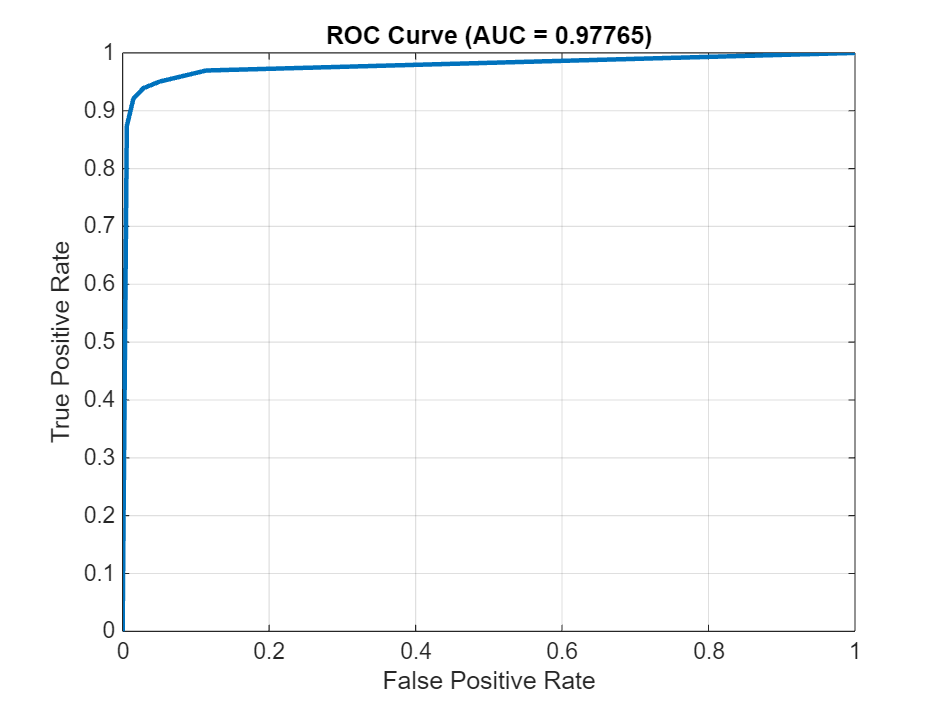


%% ---------------------------------------------------------
% 10. ROC Curve
%% ---------------------------------------------------------

[~,score_T] = predict(Mdl_T,X_test_T);

[Xroc,Yroc,~,AUC] = perfcurve(Y_test,score_T(:,2),1);

figure
plot(Xroc,Yroc,'LineWidth',2)
xlabel('False Positive Rate')
ylabel('True Positive Rate')
title(['ROC Curve (AUC = ',num2str(AUC),')'])
grid on

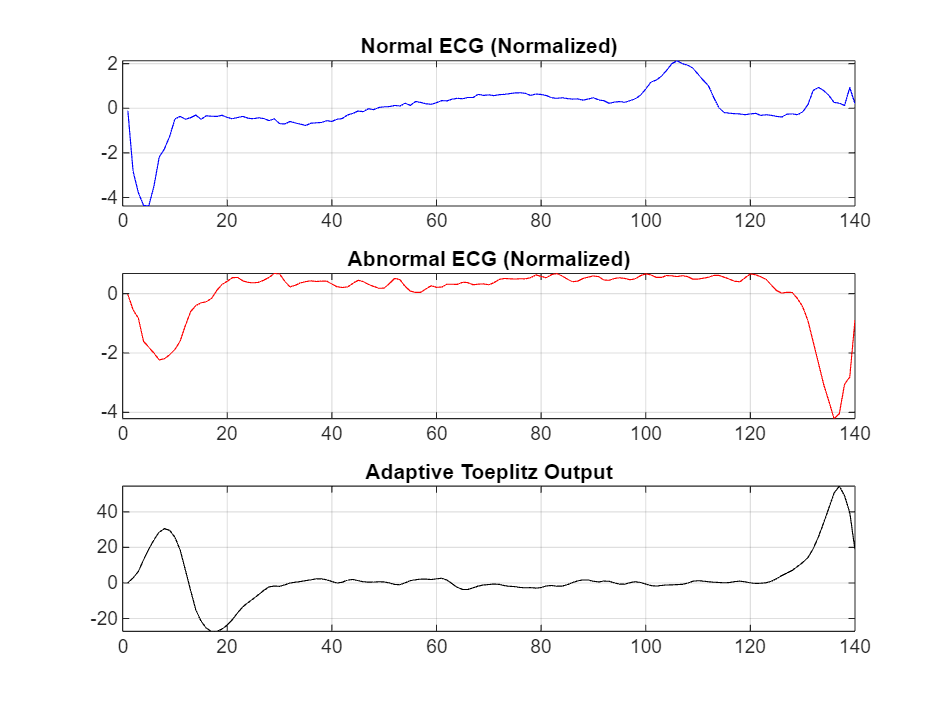


%% ---------------------------------------------------------
% 11. Example Signals
%% ---------------------------------------------------------

figure('Color','w')

normal_idx = find(labels_binary==0,1);
abnormal_idx = find(labels_binary==1,1);

subplot(3,1,1)
plot(signals(normal_idx,:),'b')
title('Normal ECG (Normalized)')
grid on

subplot(3,1,2)
plot(signals(abnormal_idx,:),'r')
title('Abnormal ECG (Normalized)')
grid on

subplot(3,1,3)
plot(adaptive_toeplitz(signals(abnormal_idx,:)),'k')
title('Adaptive Toeplitz Output')
grid on

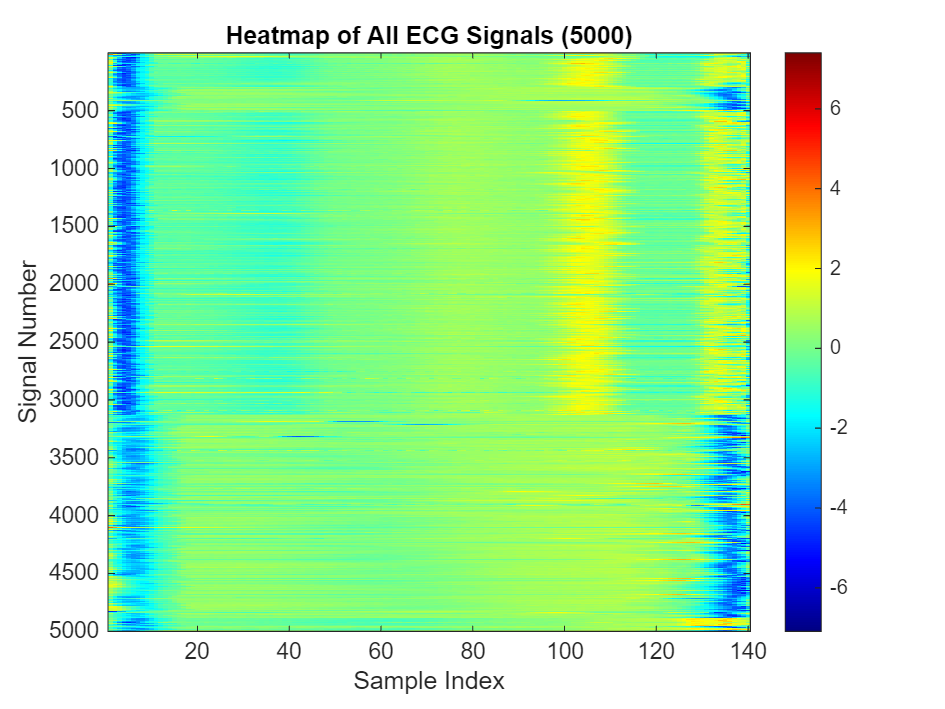


%% ---------------------------------------------------------
% 12. Heatmap of All 5000 ECG Signals
%% ---------------------------------------------------------

figure
imagesc(signals)

colorbar
xlabel('Sample Index')
ylabel('Signal Number')
title('Heatmap of All ECG Signals (5000)')
colormap(jet)

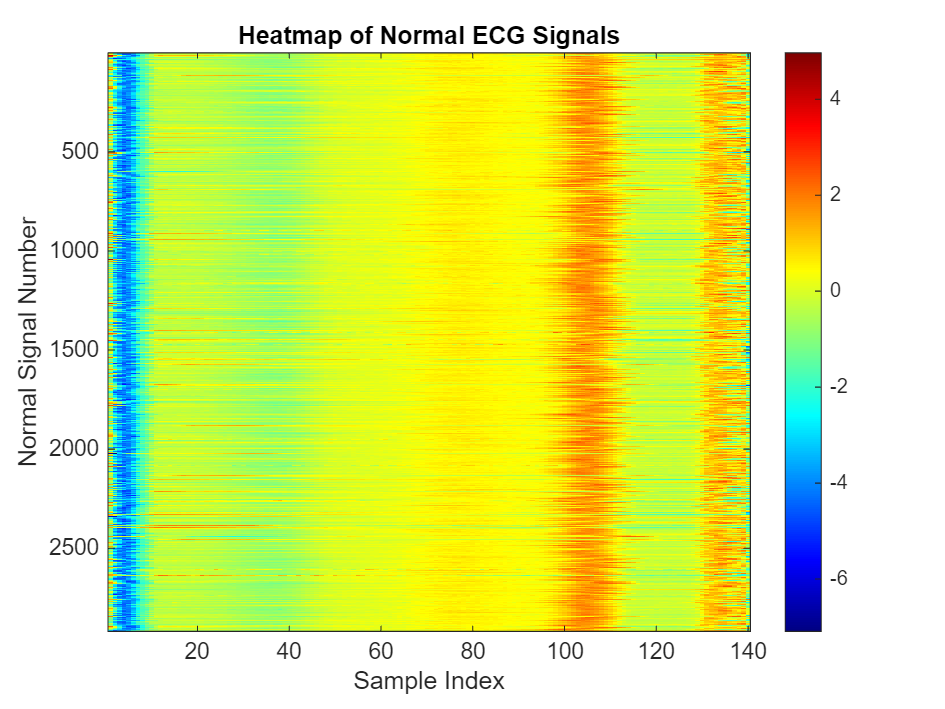


%% ---------------------------------------------------------
% 13. Heatmap of Normal ECG Signals
%% ---------------------------------------------------------

figure
imagesc(signals(labels_binary==0,:))

colorbar
xlabel('Sample Index')
ylabel('Normal Signal Number')
title('Heatmap of Normal ECG Signals')
colormap(jet)

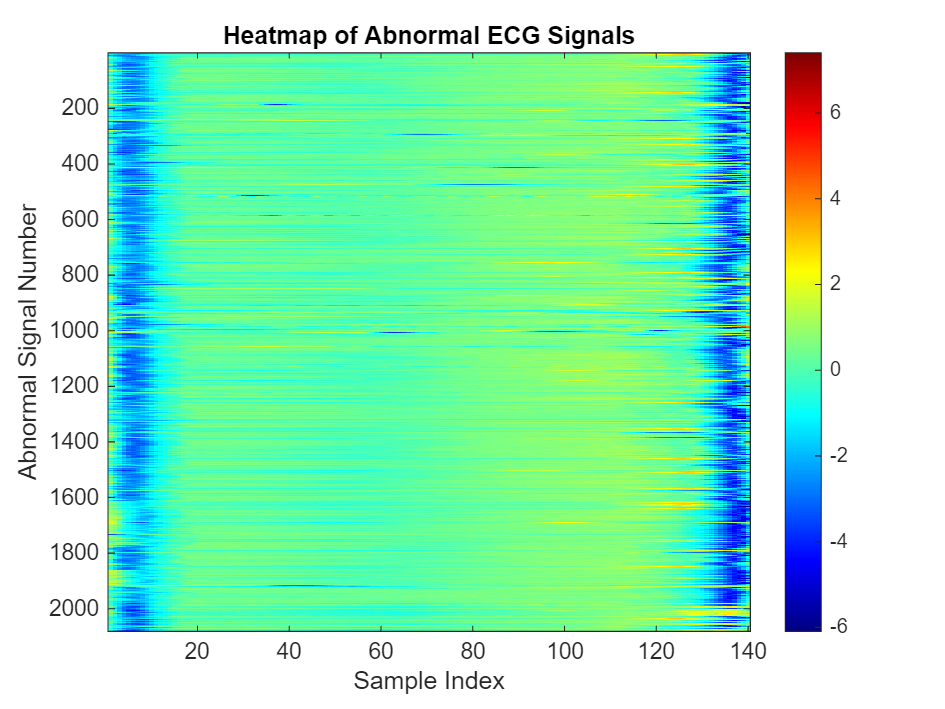


%% ---------------------------------------------------------
% 14. Heatmap of Abnormal ECG Signals
%% ---------------------------------------------------------

figure
imagesc(signals(labels_binary==1,:))

colorbar
xlabel('Sample Index')
ylabel('Abnormal Signal Number')
title('Heatmap of Abnormal ECG Signals')
colormap(jet)


toc

Elapsed time is 3.998049 seconds.
